# **RT-QIBC**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
m = matfile([dataDir filesep 'gemDbox_alldata.mat']);

clear data gate scale_edu
for e = [1:3]
    d = m.S(1,e);
    data_all{e} = d{1};
    g = m.gates_all(1,e);
    gate{e} = g{1};
    scale_edu(e) = m.medEdU_all(1,e);
    framesPerHr(e) = data_all{e}.framesPerHr;
end

**load into dataframe**

conds=[1 2];    
df = table();
rng(1)
for e = [1:3]
    dat = data_all{e};
    
    inds =dat(1).POI_time(:,1) <= 2 & dat(1).POI_time(:,1)>1 ...
        & isnan(dat(1).POI_time(:,4)) & dat(1).FarRed1 < 2^9 & dat(1).YFP1 > gate{e}.YFP1_G1(1);
    g1_edu = mean(dat(1).FarRed1(inds));
    
    for i = 1:length(conds)
        condition = conds(i);
        inds = ~isnan(dat(condition).POI_time(:,3));
        S_time = dat(condition).POI_time(inds,3);
        M_frame = dat(condition).POI(inds,1);
        M_time = dat(condition).POI_time(inds,1);
        edu = dat(condition).FarRed1(inds);      
        scale = repmat(scale_edu(e),size(edu));
%         edu_zero = repmat(gate{e}.FarRed1_G1(1),size(edu));
        edu_zero = repmat(g1_edu,size(edu));
        gmnn_thresh = repmat(gate{e}.YFP2_G1(2),size(edu));        
        cdt1_thresh = repmat(gate{e}.YFP1_S(2),size(edu));
        cdt1 = dat(condition).YFP1(inds);
        gmnn = dat(condition).YFP2(inds);
        gmnn_med = repmat(median(gmnn),size(gmnn));
        group = repmat(i,size(edu));
        exp = repmat(e, size(edu));
        df_temp = table(S_time,M_frame, edu,scale,edu_zero,cdt1,cdt1_thresh,gmnn,gmnn_med, gmnn_thresh, group,exp);
        df = [df; df_temp];
    end  
end
df.edu_corr = (df.edu - df.edu_zero) ./ df.scale;
% clear data_all data dat d

**Plot EdU levels **

Gate for early mitosis

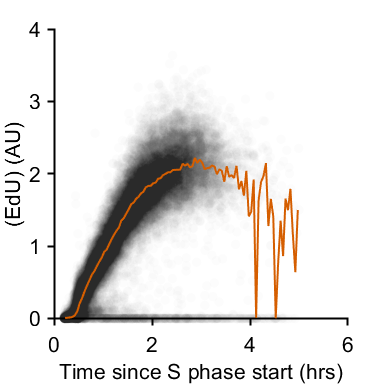


f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);

% range = linspace(0,4,10);
edges = (0:1/framesPerHr(1):10);
midpoints = edges + (edges(2) -edges(1))/2;
midpoints = midpoints(1:end-1);

inds = true(size(df.edu));
xdata = df.S_time(inds);
ydata = df.edu_corr(inds) ;
[binData, edges] = bin_xy(xdata, ydata, {'mean','median'}, 'Edges',edges);

%%% Plot black and colored by Cdt1 levels
figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
% subplot(1,2,1), 
hold on
scatter(xdata,ydata,50,'k','filled','MarkerFaceAlpha',.01);
plot(midpoints,binData.median,'LineWidth',1.5,'Color',[213 94 0]/255);
% ylim([4.5 14.5]);
% xlim([-.75 2]);
ylabel('(EdU) (AU)');xlabel('Time since S phase start (hrs)');

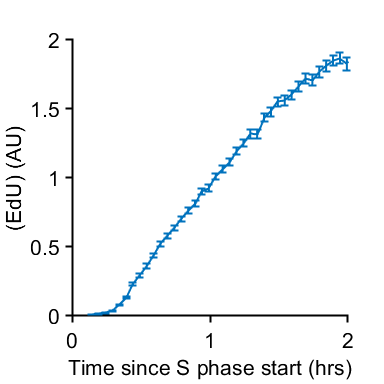


figure(f1)
hold on
errorbar(midpoints-1/12,binData.mean,2*binData.sem,'LineWidth',1.5);
xlabel('Time since S phase start (hrs)');
ylabel('(EdU) (AU)');
xlim([0 2]);
hold off
axis square
print_pdf([pwd() '\Figs\EdU_time.pdf'])


cells = length(xdata)

cells = 33208


inds = find(midpoints >= 2);
midpoints(inds(1))

ans = 2.0250

edu_2h = binData.mean(inds(1))

edu_2h = 1.8680

fraction_edu = 0.0955;
df.edu_abs = df.edu_corr * (fraction_edu / edu_2h) * 6e9;
bins = binData.numCells(1:inds(2))

bins =            0           0           0           0         689         839         764         676        1107        1682        1070         703         539         651         689         730         666         685         657         674         619         644         675         656         666         609         645         560         548         629         605         638         584         579         590         545         573         533         512         496         549         460


min(bins(bins > 0))

ans = 460

inds = df.M_frame <= 1 * framesPerHr(1) & df.S_time <= .5 & df.cdt1 > df.cdt1_thresh & ...
    ((df.gmnn > df.gmnn_med & df.group == 2) | (df.gmnn < df.gmnn_thresh  & df.group == 1));
% inds = df.M_frame <= 1.5 * framesPerHr(1) & df.S_time <= .5 & df.cdt1 > df.cdt1_thresh & ...
%     ((df.gmnn > df.gmnn_med & df.group == 2) | (df.group == 1));
df_plot = df(inds,:);

S = groupsummary(df_plot,{'exp','group'},'median',{'edu_corr','edu_abs','S_time'})

S = 6×6 table
    exp    group    GroupCount    median_edu_corr    median_edu_abs    median_S_time
    ___    _____    __________    _______________    ______________    _____________

     1       1          31            0.003104         9.5213e+05         0.29556   
     1       2          68             0.04059          1.245e+07         0.36458   
     2       1          43            0.011167         3.4254e+06         0.39611   
     2       2          72            0.054761         1.6797e+07         0.42259   
     3       1          46           0.0067884         2.0823e+06         0.31101   
     3       2          73              0.0532         1.6319e+07         0.38642   


edu_med = [];
edu_med(:,1) = S.median_edu_corr([1 3 5]);
edu_med(:,2) = S.median_edu_corr([2 4 6]);
norm_med = edu_med ./ edu_med(:,2);
mean_dmso = mean(norm_med(:,1))

mean_dmso = 0.1360

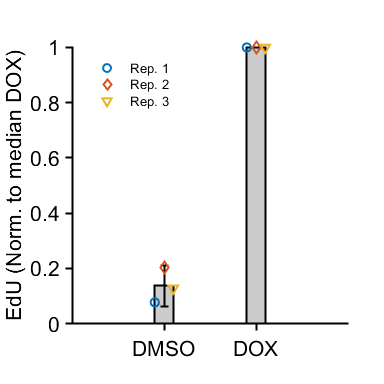

sem_dmso = 2*std(norm_med(:,1))/sqrt(3);


figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
bar([1 2],mean(norm_med),.2,'FaceColor',[.8 .8 .8],'LineWidth',1.5)
% errorbar(1,mean_dmso,neg,pos,'k+','LineWidth',1.5)
errorbar(1,mean_dmso,sem_dmso,'k+','LineWidth',1.5)
shapes = ['odv'];
jit = .1*[-1 0 1];
set(gca,'ColorOrderIndex',1)
for i=1:size(norm_med,2)
    for j = 1:size(norm_med,1)
        s(j) = scatter(i+jit(j),norm_med(j,i),40,shapes(j),'LineWidth',1.5);
    end
    set(gca,'ColorOrderIndex',1)
end
pbaspect([1 1 1])
legend(s,{'Rep. 1','Rep. 2','Rep. 3'},'FontSize',10,'Box','off','Location','northwest')
ylabel('EdU (Norm. to median DOX)')
% ylim([0 1.1])
xticks([1 2])
xlim([0 3])
xticklabels({'DMSO','DOX'})
print_pdf([pwd() '\Figs\EdU_corr_bar.pdf'])


mean_dmso + [-1 1]*sem_dmso

ans =     0.0619    0.2101



mean_edu_dmso_abs = mean(S.median_edu_abs([1 3 5]))

mean_edu_dmso_abs = 2.1533e+06

mean_edu_dox_abs = mean(S.median_edu_abs([2 4 6]))

mean_edu_dox_abs = 1.5189e+07

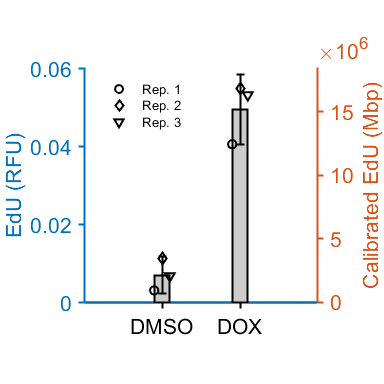


mean_dmso = mean(edu_med(:,1));
sem_dmso = 2*std(edu_med(:,1))/sqrt(3);
mean_dox = mean(edu_med(:,2));
sem_dox = 2*std(edu_med(:,2))/sqrt(3);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
yyaxis left
bar([1 2],mean(edu_med),.2,'FaceColor',[.8 .8 .8],'LineWidth',1.5)
% errorbar(1,mean_dmso,neg,pos,'k+','LineWidth',1.5)
errorbar(1,mean_dmso,sem_dmso,'k+','LineWidth',1.5)
errorbar(2,mean_dox,sem_dox,'k+','LineWidth',1.5)
shapes = ['odv'];
jit = .1*[-1 0 1];
for i=1:size(edu_med,2)
    for j = 1:size(edu_med,1)
        s(j) = scatter(i+jit(j),edu_med(j,i),40,shapes(j),'LineWidth',1.5,'MarkerEdgeColor','k');
    end
    set(gca,'ColorOrderIndex',1)
end
pbaspect([1 1 1])
legend(s,{'Rep. 1','Rep. 2','Rep. 3'},'FontSize',10,'Box','off','Location','northwest')
ylabel('EdU (RFU)')
% ylim([0 1.1])
xticks([1 2])
xlim([0 3])
xticklabels({'DMSO','DOX'})
yyaxis right
ylim([0 0.06 * (fraction_edu / edu_2h) * 6e9])
ylabel('Calibrated EdU (Mbp)')
print_pdf([pwd() '\Figs\EdU_cal_val_bar.pdf'])

inds = df.M_frame <= 1 * framesPerHr(1) & df.S_time <= .5 & df.cdt1 > 2*df.cdt1_thresh & ...
    ((df.gmnn > df.gmnn_med & df.group == 2) | (df.gmnn < df.gmnn_thresh  & df.group == 1));
% inds = df.M_frame <= 1.5 * framesPerHr(1) & df.S_time <= .5 & df.cdt1 > df.cdt1_thresh & ...
%     ((df.gmnn > df.gmnn_med & df.group == 2) | (df.group == 1));
df_plot = df(inds,:);

S = groupsummary(df_plot,{'exp','group'},'median',{'edu_corr','edu_abs','S_time'})

S = 6×6 table
    exp    group    GroupCount    median_edu_corr    median_edu_abs    median_S_time
    ___    _____    __________    _______________    ______________    _____________

     1       1          31            0.003104         9.5213e+05         0.29556   
     1       2          66            0.034211         1.0494e+07         0.36028   
     2       1          39            0.011085         3.4001e+06         0.39611   
     2       2          70            0.054122         1.6601e+07         0.42194   
     3       1          46           0.0067884         2.0823e+06         0.31101   
     3       2          68            0.053339         1.6361e+07         0.38169   


edu_med = [];
edu_med(:,1) = S.median_edu_corr([1 3 5]);
edu_med(:,2) = S.median_edu_corr([2 4 6]);
norm_med = edu_med ./ edu_med(:,2);
mean_dmso = mean(norm_med(:,1))

mean_dmso = 0.1409

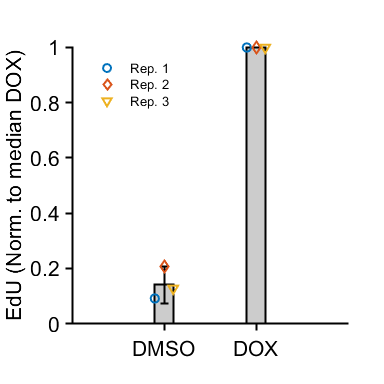

sem_dmso = 2*std(norm_med(:,1))/sqrt(3);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
bar([1 2],mean(norm_med),.2,'FaceColor',[.8 .8 .8],'LineWidth',1.5)
% errorbar(1,mean_dmso,neg,pos,'k+','LineWidth',1.5)
errorbar(1,mean_dmso,sem_dmso,'k+','LineWidth',1.5)
shapes = ['odv'];
jit = .1*[-1 0 1];
set(gca,'ColorOrderIndex',1)
for i=1:size(norm_med,2)
    for j = 1:size(norm_med,1)
        s(j) = scatter(i+jit(j),norm_med(j,i),40,shapes(j),'LineWidth',1.5);
    end
    set(gca,'ColorOrderIndex',1)
end
pbaspect([1 1 1])
legend(s,{'Rep. 1','Rep. 2','Rep. 3'},'FontSize',10,'Box','off','Location','northwest')
ylabel('EdU (Norm. to median DOX)')
% ylim([0 1.1])
xticks([1 2])
xlim([0 3])
xticklabels({'DMSO','DOX'})

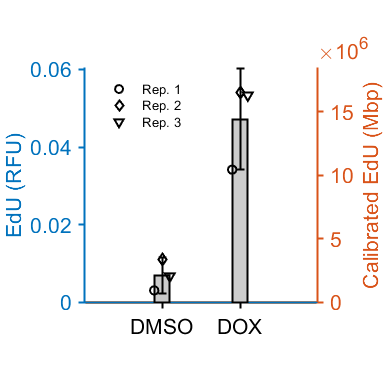

mean_dmso = mean(edu_med(:,1));
sem_dmso = 2*std(edu_med(:,1))/sqrt(3);
mean_dox = mean(edu_med(:,2));
sem_dox = 2*std(edu_med(:,2))/sqrt(3);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
yyaxis left
bar([1 2],mean(edu_med),.2,'FaceColor',[.8 .8 .8],'LineWidth',1.5)
% errorbar(1,mean_dmso,neg,pos,'k+','LineWidth',1.5)
errorbar(1,mean_dmso,sem_dmso,'k+','LineWidth',1.5)
errorbar(2,mean_dox,sem_dox,'k+','LineWidth',1.5)
shapes = ['odv'];
jit = .1*[-1 0 1];
for i=1:size(edu_med,2)
    for j = 1:size(edu_med,1)
        s(j) = scatter(i+jit(j),edu_med(j,i),40,shapes(j),'LineWidth',1.5,'MarkerEdgeColor','k');
    end
    set(gca,'ColorOrderIndex',1)
end
pbaspect([1 1 1])
legend(s,{'Rep. 1','Rep. 2','Rep. 3'},'FontSize',10,'Box','off','Location','northwest')
ylabel('EdU (RFU)')
% ylim([0 1.1])
xticks([1 2])
xlim([0 3])
xticklabels({'DMSO','DOX'})
yyaxis right
ylim([0 0.06 * (fraction_edu / edu_2h) * 6e9])
ylabel('Calibrated EdU (Mbp)')

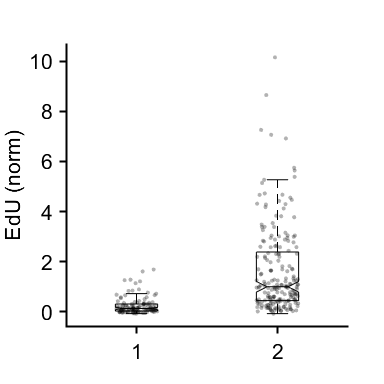


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
group = df_plot.group;
ally = df_plot.edu_corr;
scale = median(ally(group == 2));
ally = ally/scale;

boxplot(ally,group,'Notch','on','Symbol','','Color','k');
hold on
groupcol = [[0 0 0];[0 0 0]];
jit = 0.3*rand(size(group))-.15;
scatter(group+jit, (ally), 10,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('EdU (norm)')
% xticklabels({'G1','S siCtrl','S siGMNN','S siCtrl MLN','S siGMNN MLN'})
box off
axis square

% ylim([0 8000])
% print_pdf([pwd() '\Figs\gmnn_compare.pdf'])

num_cells = splitapply(@length,ally,group)

num_cells =    116
   204
